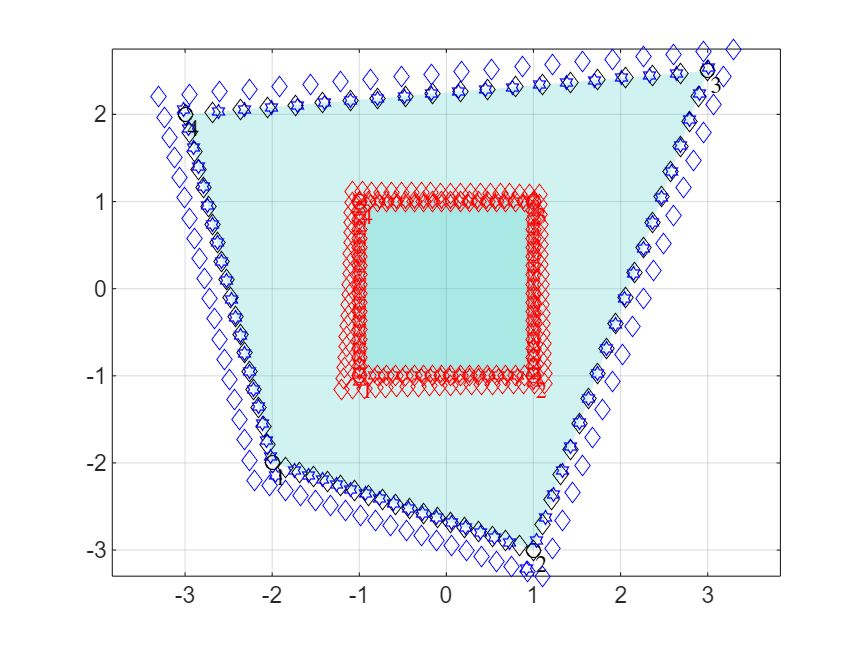

clear
clc

ksi_i = [-1,+1,+1,-1]';
eta_i = [-1,-1,+1,+1]';

x = [-2,+1,+3,-3];
y = [-2,-3,+2.5,+2];

N = {@(ksi,eta) 0.25 * (1 - ksi) .* (1 - eta);
    @(ksi,eta) 0.25 * (1 + ksi) .* (1 - eta);
    @(ksi,eta) 0.25 * (1 + ksi) .* (1 + eta);
    @(ksi,eta) 0.25 * (1 - ksi) .* (1 + eta);};
dNdksi = {@(ksi,eta) -0.25 * (1 - eta);
    @(ksi,eta) +0.25 * (1 + eta);
    @(ksi,eta) +0.25 * (1 + eta);
    @(ksi,eta) -0.25 * (1 - eta);};
dNdeta = {@(ksi,eta) -0.25 * (1 - ksi);
    @(ksi,eta) -0.25 * (1 - ksi);
    @(ksi,eta) +0.25 * (1 + ksi);
    @(ksi,eta) +0.25 * (1 + ksi);};

n = 20;
ksi0 = [linspace(-1,1,n),ones(1,n),linspace(1,-1,n),-ones(1,n)];
eta0 = [-ones(1,n),linspace(-1,1,n),ones(1,n),linspace(1,-1,n)];

x0 = zeros(size(ksi0));
y0 = zeros(size(eta0));
for i = 1:4
    x0 = x0 + N{i}(ksi0,eta0) * x(i);
    y0 = y0 + N{i}(ksi0,eta0) * y(i);
end
r = 1.1;
x1 = x0(:)*r;
y1 = y0(:)*r;

ksi1 = 0;
eta1 = 0;
for iter = 1:100
    f1 = -x1; f2 = -y1;
    f1ksi = 0; f1eta = 0;
    f2ksi = 0; f2eta = 0;
    for i = 1:4
        f1 = f1 + N{i}(ksi1,eta1) * x(i);
        f2 = f2 + N{i}(ksi1,eta1) * y(i);
        f1ksi = f1ksi + dNdksi{i}(ksi1,eta1) * x(i);
        f1eta = f1eta + dNdeta{i}(ksi1,eta1) * x(i);
        f2ksi = f2ksi + dNdksi{i}(ksi1,eta1) * y(i);
        f2eta = f2eta + dNdeta{i}(ksi1,eta1) * y(i);
    end
    J = f1ksi .* f2eta - f1eta .* f2ksi;
    ksi1 = ksi1 - (f1.*f2eta - f2.*f1eta)./J;
    eta1 = eta1 - (f1ksi.*f2 - f2ksi.*f1)./J;
    if (all(abs(f1) <= 1e-16) && all(abs(f2) <= 1e-16))
        break
    end
end

% for i = 1:length(ksi1)
%     if abs(ksi1(i))>1
%         ksi1(i) = ksi1(i)/abs(ksi1(i)); %#ok
%     end
%     if abs(eta1(i))>1
%         eta1(i) = eta1(i)/abs(eta1(i)); %#ok
%     end
% end

for point = 1:length(x1)
    if ksi1(point) < -1
        ksi2(point) = -1; %#ok
        eta2(point) = eta1(point) * ksi2(point)/ksi1(point); %#ok
    elseif ksi1(point) > 1
        ksi2(point) = 1; %#ok
        eta2(point) = eta1(point) * ksi2(point)/ksi1(point); %#ok
    elseif eta1(point) < -1
        eta2(point) = -1; %#ok
        ksi2(point) = ksi1(point) * eta2(point)/eta1(point); %#ok
    elseif eta1(point) > 1
        eta2(point) = 1; %#ok
        ksi2(point) = ksi1(point) * eta2(point)/eta1(point); %#ok
    else
        ksi2(point) = ksi1(point); %#ok
        eta2(point) = eta1(point); %#ok
    end
    x2(point) = 0; y2(point) = 0; %#ok
    for i = 1:4
        x2(point) = x2(point) + ...
            N{i}(ksi2(point),eta2(point)) * x(i);
        y2(point) = y2(point) + ...
            N{i}(ksi2(point),eta2(point)) * y(i);
    end
end

sqrt((ksi2-ksi1).^2 + (eta2-eta1).^2);
sqrt((x2-x1).^2 + (y2-y1).^2);

figure()
scatter(ksi_i,eta_i,'r')
hold on
scatter(x,y,'k')
trisurf(delaunay(ksi_i,eta_i),ksi_i,eta_i,eta_i*0, ...
        'FaceAlpha',0.2, ...
        'EdgeColor','None');
trisurf(delaunay(x,y),x,y,y*0, ...
        'FaceAlpha',0.2, ...
        'EdgeColor','None');
scatter(ksi0,eta0,'rd')
scatter(x0,y0,'kd')

scatter(ksi1,eta1,'rd')
scatter(x1,y1,'bd')
scatter(ksi2,eta2,'rh')
scatter(x2,y2,'bh')
for i = 1:4
    text(x(i),y(i),string(i), ...
        "Interpreter","latex", ...
        "VerticalAlignment","top")
    text(ksi_i(i),eta_i(i),string(i), ...
        "Interpreter","latex", ...
        "VerticalAlignment","top", ...
        "Color",'r')
end
hold off
box on
grid on
axis equal